# Optimal AR model to fit a target PSD through pole-placement approach

## Introduction

In this tutorial you will learn how to obtain an optimal AR model that reproduces a predefined spectrum. To this end, a method based on pole-placement will be used. You can find more details on the method in **[1]**.

Four different optimal models are obtained and compared, resulting from the combination of the following options:

- global fitting (over the whole frequency range) or local fitting (within a specific frequency range).

- fitting the spectrum $S(f)$ or the product $f \cdot S(f)$.

The dataset employed in this tutorial is '*datasets/dataset_03_Mann_1V*', which includes a true spectrum according to the Mann's model.

**[1] **Elagamy, M. et al. Optimal autoregressive models for synthetic generation of turbulence. Implications of reproducing the spectrum or the autocovariance function. 17th European Academy of Wind Energy (EWEA) PhD Seminar on Wind Energy, Porto (Portugal), 2021.

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

% AR parameters
N_real      = 2;    % number of real poles of the AR model
N_complex   = 1;    % number of complex conjugate pairs of the AR model
                    % The AR order is p = N_real + 2*N_complex

% frequency range for local fitting
f_local_start = 3e-2;
f_local_end   = 3e-1;


%%% Plot parameters
font_size       = 13;
figure_position = [0 0 1000 350];
polar_position  = [0 0 350 350];
color_rectangle = [1 1 0.85];
CC              = colororder;
color_target    = [0 0 0];
color_AR        = [CC(1,:);CC(5,:);CC(3,:);CC(4,:)];

Load the dataset. It consists of two objects, one in the form of a `data` object, and one in the form of a `S` object. Set the Mann spectrum as the target spectrum.

load dataset_03_Mann_1V.mat S_Mann

S_Target = S_Mann;

Initialise an AR object, with the fields required by function opt_AR_S_through_pole_placement.

AR0 = initialise_AR('N_real',N_real,'N_complex',N_complex);

Define the score function to be employed throughout this tutorial. The score function is a function handle pointing at any of the score functions contained in folder *funs_score/*. The chosen one computes the root mean squared error between two provided vectors. A weight vector can be included.

fun_score = @fun_rmse_1V;

### Model AR-1: Fitting a target PSD globally

Obtain an optimal model that globally fits the target PSD. Note that the fitting is based on the frequency points at which the target is defined. Since the target PSD is to be represented in x-log scale, it is defined in a frenquency vector also in logarithmic scale (see tutorial *getting_S_from_data_through_sample_spectrum* for details). Different frequency vectors where the target is evaluated may lead to different optimal models.

[AR_1, S_AR_1] = opt_AR_S_through_pole_placement(S_Target, AR0, fun_score);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


You can visualize the AR model coefficients and the optimal position of the poles. As expected, poles remain within the unit circle to keep the AR model stationary, as this is a constraint in the optimisation process.

disp(strrep(['Regression coefficients: (' sprintf(' %.2f,', ... 
             AR_1.parameters.phi_vector) ')'], ',)', ' )'))

Regression coefficients: ( 2.04, -1.60, 0.60, -0.05 )


fprintf('Noise coefficient: %.2f\n', AR_1.parameters.sigma)

Noise coefficient: 0.29


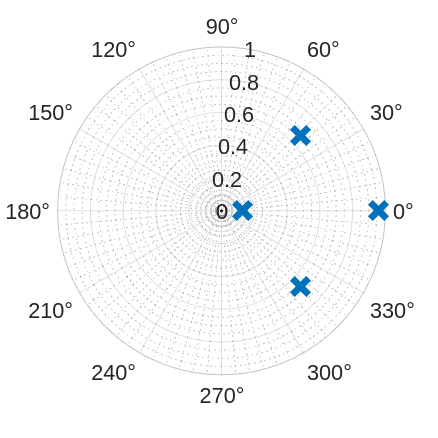


[theta , rho] = cart2pol(real(AR_1.poles.poles_AR),imag(AR_1.poles.poles_AR));

figure
polarplot(theta,rho,'x','MarkerSize',14,'LineWidth',4,'color',color_AR(1,:))
set(gca,'fontsize',font_size)
set(gcf,'position',polar_position) 
grid minor

Plot the results. On the left is the representation of $S(f)$, which is the one employed for the fitting. On the right is the representation of $f \cdot S(f)$, usually employed in turbulent wind characterisation.

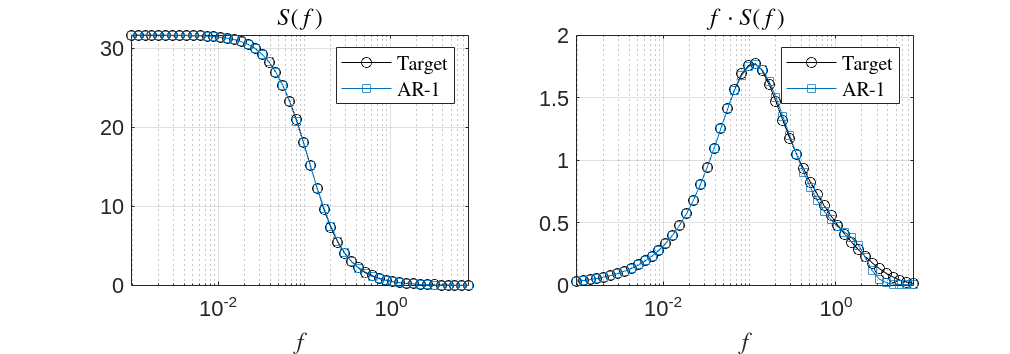

figure


subplot(1,2,1)

x = S_Target.x_values;
y = S_Target.y_values;
plot(x,y,'O-','Color',color_target)
hold on
x = S_AR_1.x_values;
y = S_AR_1.y_values;
plot(x,y,'s-','Color',color_AR(1,:))

grid on
legend('Target','AR-1','Interpreter','latex')
xlabel('$f$','Interpreter','latex')
title('$S(f)$','Interpreter','latex')

set(gca,'XScale','log')
set(gca,'fontsize',font_size)


subplot(1,2,2)

x = S_Target.x_values;
y = S_Target.y_values;
plot(x,x.*y,'O-','Color',color_target)
hold on
x = S_AR_1.x_values;
y = S_AR_1.y_values;
plot(x,x.*y,'s-','Color',color_AR(1,:))

grid on
legend('Target','AR-1','Interpreter','latex')
xlabel('$f$','Interpreter','latex')
title('$f \cdot S(f)$','Interpreter','latex')

set(gca,'XScale','log')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position) 

### Model AR-2: Fitting a target PSD locally

To focus the optimisation in a specific frequency range, a weight vector can be employed. Weights are applied to the error between target and AR PSD. In this case, weights will be set to 1 within the range and 0 out of the range.

weights_vector_locally = zeros(numel(S_Target.x_values),1);
positions = find(S_Target.x_values>=f_local_start & ...
                 S_Target.x_values<=f_local_end);
weights_vector_locally(positions) = 1;

Obtain optimal model that globally fits the target PSD.

[AR_2, S_AR_2] = opt_AR_S_through_pole_placement(S_Target, AR0, fun_score, ...
                                         weights_vector_locally);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Visualize the AR model coefficients and the optimal position of the poles. Check that they are different from those of model AR-1.

disp(strrep(['Regression coefficients: (' sprintf(' %.2f,',...
             AR_2.parameters.phi_vector) ')'], ',)', ' )'))

Regression coefficients: ( 1.33, -0.53, 0.37, -0.19 )


fprintf('Noise coefficient: %.2f\n', AR_2.parameters.sigma)

Noise coefficient: 0.41


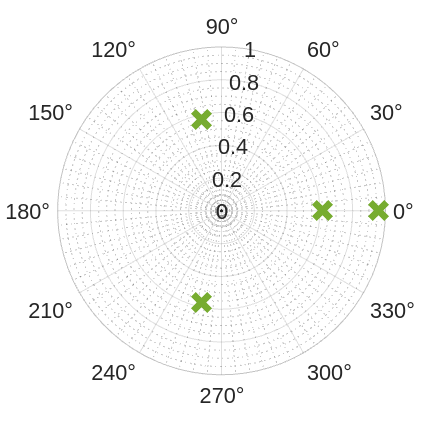


[theta , rho] = cart2pol(real(AR_2.poles.poles_AR),imag(AR_2.poles.poles_AR));

figure
polarplot(theta,rho,'x','MarkerSize',14,'LineWidth',4,'color',color_AR(2,:))
set(gca,'fontsize',font_size)
set(gcf,'position',polar_position) 
grid minor

Plot the results.

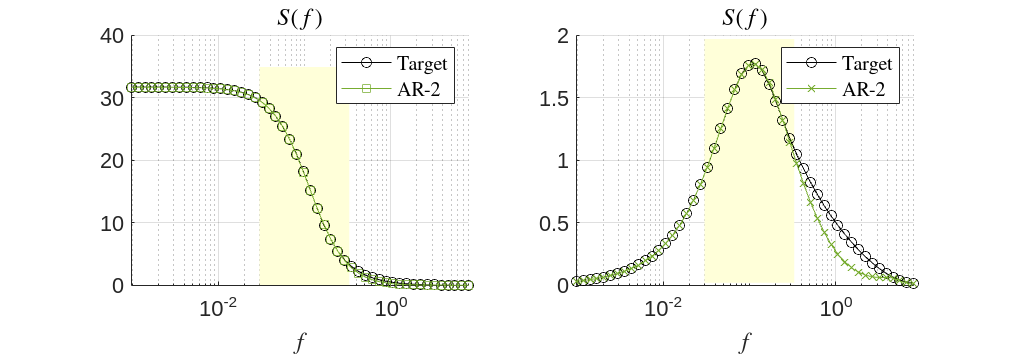

figure


subplot(1,2,1)

rectangle('Position', [f_local_start 0.02 f_local_end...
                       1.1*max(S_Target.y_values)], ...
          'FaceColor',color_rectangle,...
          'EdgeColor', 'None');
hold on
x = S_Target.x_values;
y = S_Target.y_values;
plot(x,y,'O-','Color',color_target)
hold on
x = S_AR_2.x_values;
y = S_AR_2.y_values;
plot(x,y,'s-','color',color_AR(2,:))

grid on
legend('Target','AR-2','Interpreter','latex')
xlabel('$f$','Interpreter','latex')
title('$S(f)$','Interpreter','latex')

set(gca,'XScale','log')
set(gca,'fontsize',font_size)


subplot(1,2,2)

rectangle('Position', [f_local_start 0.02 f_local_end ...
                       1.1*max(S_Target.x_values.*S_Target.y_values)], ...
          'FaceColor',color_rectangle,...
          'EdgeColor', 'None');
hold on
x = S_Target.x_values;
y = S_Target.y_values;
plot(x,x.*y,'O-','color', color_target)
x = S_AR_2.x_values;
y = S_AR_2.y_values;
plot(x,x.*y,'x-','color', color_AR(2,:))

grid on
legend('Target','AR-2','Interpreter','latex')
xlabel('$f$','Interpreter','latex')
title('$S(f)$','Interpreter','latex')

set(gca,'XScale','log')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Model AR-3: Fitting the product $f\cdot S(f)$ globally

To globally fit a PSD in terms of $f \cdot  S(f)$, the weight vector can be employed. Since the error between target and AR PSD is squared, the weight corresponding to frequency $f$  has to be set to the squared of the frequency, $f^2$.

weights_vector_fS = S_Target.x_values.*S_Target.x_values;

Obtain optimal model that globally fits the product $f \cdot  S(f)$.

[AR_3, S_AR_3] = opt_AR_S_through_pole_placement(S_Target, AR0, fun_score, ...
                                         weights_vector_fS);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Visualize the AR model coefficients and the optimal position of the poles. Check that they are different from those of previous models.

disp(strrep(['Regression coefficients: (' sprintf(' %.2f,',...
             AR_3.parameters.phi_vector) ')'], ',)', ' )'))

Regression coefficients: ( 1.40, -0.46, -0.11, 0.13 )


fprintf('Noise coefficient: %.2f\n', AR_3.parameters.sigma)

Noise coefficient: 0.50


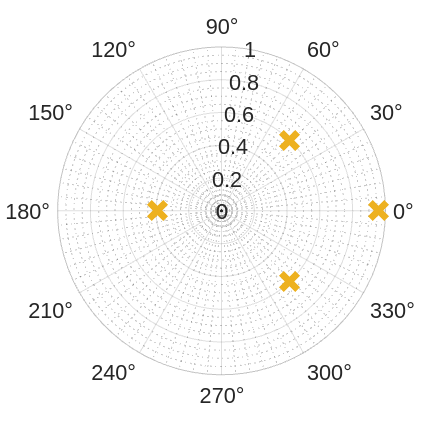


[theta , rho] = cart2pol(real(AR_3.poles.poles_AR),imag(AR_3.poles.poles_AR));

figure
polarplot(theta,rho,'x','MarkerSize',14,'LineWidth',4,'color',color_AR(3,:))
set(gca,'fontsize',font_size)
set(gcf,'position',polar_position) 
grid minor

Plot the results. Now the fitting is better in the right figure.

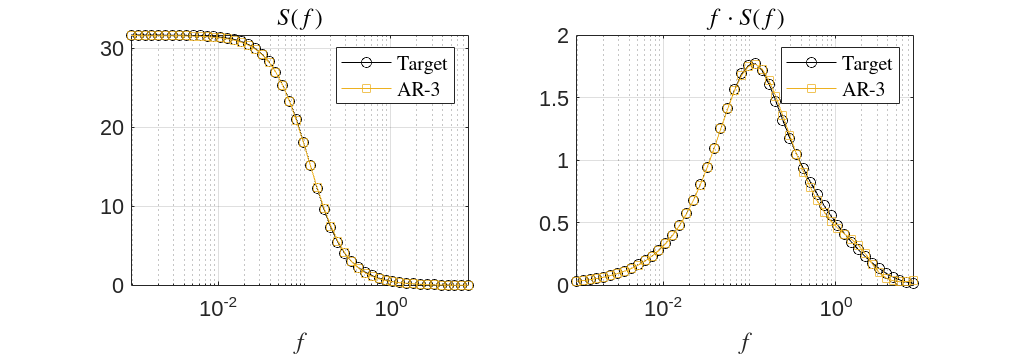

figure


subplot(1,2,1)

x = S_Target.x_values;
y = S_Target.y_values;
plot(x,y,'O-','Color',color_target)
hold on
x = S_AR_3.x_values;
y = S_AR_3.y_values;
plot(x,y,'s-','Color',color_AR(3,:))

grid on
legend('Target','AR-3','Interpreter','latex')
xlabel('$f$','Interpreter','latex')
title('$S(f)$','Interpreter','latex')

set(gca,'XScale','log')
set(gca,'fontsize',font_size)

subplot(1,2,2)

x = S_Target.x_values;
y = S_Target.y_values;
plot(x,x.*y,'O-','Color',color_target)
hold on
x = S_AR_3.x_values;
y = S_AR_3.y_values;
plot(x,x.*y,'s-','Color',color_AR(3,:))

grid on
legend('Target','AR-3','Interpreter','latex')
xlabel('$f$','Interpreter','latex')
title('$f \cdot S(f)$','Interpreter','latex')

set(gca,'XScale','log')
set(gca,'fontsize',font_size)


set(gcf,'position',figure_position) 

### Model AR-4: Fitting the product $f\cdot S(f)$ locally

In this case, the weight vector combines the two previous cases.

weights_vector_locally_fS = weights_vector_locally .* weights_vector_fS;

Obtain optimal model that globally fits the target PSD.

[AR_4, S_AR_4] = opt_AR_S_through_pole_placement(S_Target, AR0, fun_score,...
                                         weights_vector_locally_fS);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Visualize the AR model coefficients and the optimal position of the poles. Check that they are different from those of previous models.

disp(strrep(['Regression coefficients: (' sprintf(' %.2f,', ...
            AR_4.parameters.phi_vector) ')'], ',)', ' )'))

Regression coefficients: ( 0.87, -0.00, 0.21, -0.12 )


fprintf('Noise coefficient: %.2f\n', AR_4.parameters.sigma)

Noise coefficient: 0.72


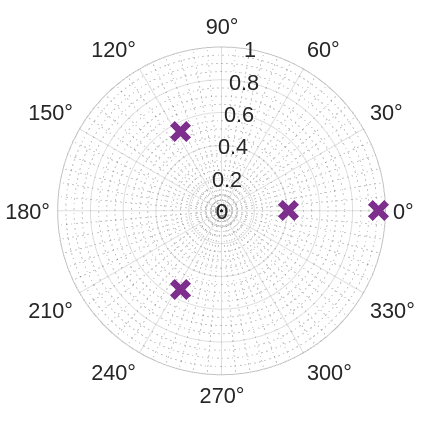


[theta , rho] = cart2pol(real(AR_4.poles.poles_AR),imag(AR_4.poles.poles_AR));

figure
polarplot(theta,rho,'x','MarkerSize',14,'LineWidth',4,'color',color_AR(4,:))
set(gca,'fontsize',font_size)
set(gcf,'position',polar_position) 
grid minor

Plot the results.

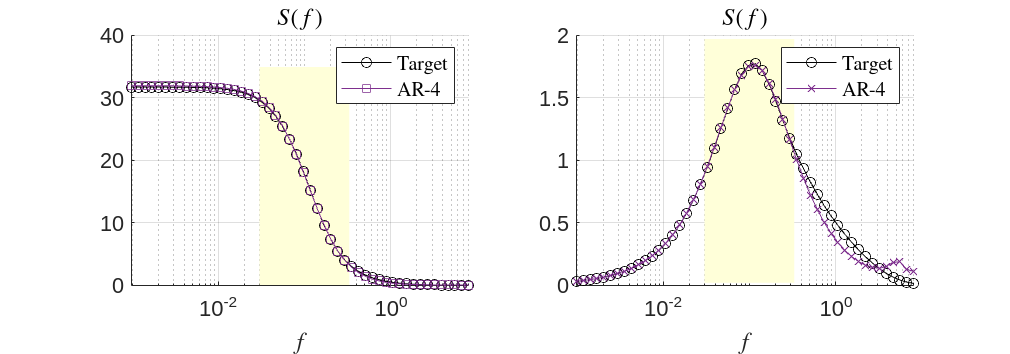

figure


subplot(1,2,1)

rectangle('Position', [f_local_start 0.02 f_local_end ...
                       1.1*max(S_Target.y_values)], ...
          'FaceColor',color_rectangle,...
          'EdgeColor', 'None');
hold on
x = S_Target.x_values;
y = S_Target.y_values;
plot(x,y,'O-','Color',color_target)
hold on
x = S_AR_4.x_values;
y = S_AR_4.y_values;
plot(x,y,'s-','color',color_AR(4,:))

grid on
legend('Target','AR-4','Interpreter','latex')
xlabel('$f$','Interpreter','latex')
title('$S(f)$','Interpreter','latex')

set(gca,'XScale','log')
set(gca,'fontsize',font_size)


subplot(1,2,2)

rectangle('Position', [f_local_start 0.02 f_local_end ...
                       1.1*max(S_Target.x_values.*S_Target.y_values)], ...
          'FaceColor',color_rectangle,...
          'EdgeColor', 'None');
hold on
x = S_Target.x_values;
y = S_Target.y_values;
plot(x,x.*y,'O-','color', color_target)
x = S_AR_4.x_values;
y = S_AR_4.y_values;
plot(x,x.*y,'x-','color',color_AR(4,:))

grid on
legend('Target','AR-4','Interpreter','latex')
xlabel('$f$','Interpreter','latex')
title('$S(f)$','Interpreter','latex')

set(gca,'XScale','log')
set(gca,'fontsize',font_size)


set(gcf,'position',figure_position)

### Comparison

For each model, global and local errors are computed for $S(f)$ and $f\cdot S(f)$. In the following figures you can see that each model has the minimum error under the criterion employed to obtain it. For example, model AR-1 has the lowest global error based on $S(f)$ fitting (plot on the left), and model AR-4 has the lowest local error based on $f\cdot S(f)$ fitting (plot on the right).

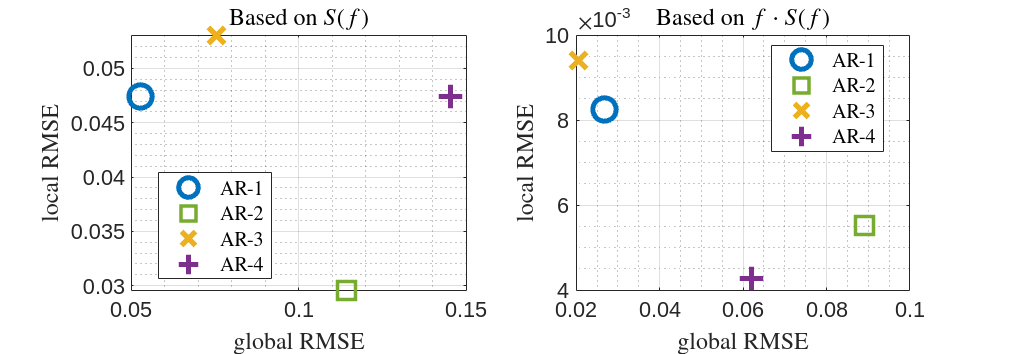

RMSE_global_S (1) = fun_rmse_1V(S_Target.y_values,S_AR_1.y_values);
RMSE_global_S (2) = fun_rmse_1V(S_Target.y_values,S_AR_2.y_values);
RMSE_global_S (3) = fun_rmse_1V(S_Target.y_values,S_AR_3.y_values);
RMSE_global_S (4) = fun_rmse_1V(S_Target.y_values,S_AR_4.y_values);

RMSE_local_S (1) = fun_rmse_1V(S_Target.y_values,...
                               S_AR_1.y_values,weights_vector_locally);
RMSE_local_S (2) = fun_rmse_1V(S_Target.y_values,...
                               S_AR_2.y_values,weights_vector_locally);
RMSE_local_S (3) = fun_rmse_1V(S_Target.y_values,...
                               S_AR_3.y_values,weights_vector_locally);
RMSE_local_S (4) = fun_rmse_1V(S_Target.y_values,...
                               S_AR_4.y_values,weights_vector_locally);

RMSE_global_fS (1) = fun_rmse_1V(S_Target.y_values,...
                                 S_AR_1.y_values,weights_vector_fS);
RMSE_global_fS (2) = fun_rmse_1V(S_Target.y_values, ...
                                 S_AR_2.y_values,weights_vector_fS);
RMSE_global_fS (3) = fun_rmse_1V(S_Target.y_values, ...
                                 S_AR_3.y_values,weights_vector_fS);
RMSE_global_fS (4) = fun_rmse_1V(S_Target.y_values, ...
                                 S_AR_4.y_values,weights_vector_fS);

RMSE_local_fS (1) = fun_rmse_1V(S_Target.y_values, ...
                                S_AR_1.y_values,weights_vector_locally_fS);
RMSE_local_fS (2) = fun_rmse_1V(S_Target.y_values, ...
                                S_AR_2.y_values,weights_vector_locally_fS);
RMSE_local_fS (3) = fun_rmse_1V(S_Target.y_values, ...
                                S_AR_3.y_values,weights_vector_locally_fS);
RMSE_local_fS (4) = fun_rmse_1V(S_Target.y_values, ...
                                S_AR_4.y_values,weights_vector_locally_fS);


figure

markers = {'O', 's', 'x', '+'};


subplot(1,2,1)

for ii = 1:4
    x = RMSE_global_S(ii);
    y = RMSE_local_S(ii);
    plot(x,y,markers{ii},'color',color_AR(ii,:),'MarkerSize',14,'linewidth',3)
    hold on
end

grid on
grid minor
title('Based on $S(f)$','Interpreter','latex')
xlabel('global RMSE','Interpreter','latex')
ylabel('local RMSE','Interpreter','latex')
legend({'AR-1', 'AR-2', 'AR-3', 'AR-4'},'Location','best','Interpreter','latex')

set(gca,'fontsize',font_size)


subplot(1,2,2)

for ii = 1:4
    x = RMSE_global_fS(ii);
    y = RMSE_local_fS(ii);
    plot(x,y,markers{ii},'color',color_AR(ii,:),'MarkerSize',14,'linewidth',3)
    hold on
end

grid on
grid minor
title('Based on $f \cdot S(f)$','Interpreter','latex')
xlabel('global RMSE','Interpreter','latex')
ylabel('local RMSE','Interpreter','latex')
legend({'AR-1', 'AR-2', 'AR-3', 'AR-4'},'Location','best','Interpreter','latex')

set(gca,'fontsize',font_size)


set(gcf,'position',figure_position)

## Remarks

- Note that the obtained AR(4) models are for 2 real poles and 1 pair of complex conjugates. Results may be different for AR(4) models based on 2 pairs of complex conjugates. You can check this by setting `N_real=0` and `N_complex=2`.

- Also, the accuracy of the fitting improves with the model order, as more degrees of freedom (model parameters) are available for the optimisation. You can chech this by increasing the value of parameters `N_real` and `N_complex`.

- Sometimes, the optimal position of a pair of complex conjugates is very close to the real axis (small imaginary part of the poles). This suggests that `N_real` should be increased, and `N_complex` decreased.

- Once an optimal AR model has been obtained, it can be employed to generate synthetic time series, see tutorial *getting_data_from_AR*.